## 文件的初始化工作

clear;
close all;
clc;
rng(2023);                  %固定随机种子，保证结果可复现

## 参数设置

V_max = 10;
sigma_x=sqrt(2);            %拉普拉斯分布的系数(根号2)
N = 1000000;                %拉普拉斯分布下采样点数
A = randlap(N, sigma_x);    %拉普拉斯分布下的采样
mu = 255;                   %μ取值

## 画出拉普拉斯分布生成采样的幅度分布

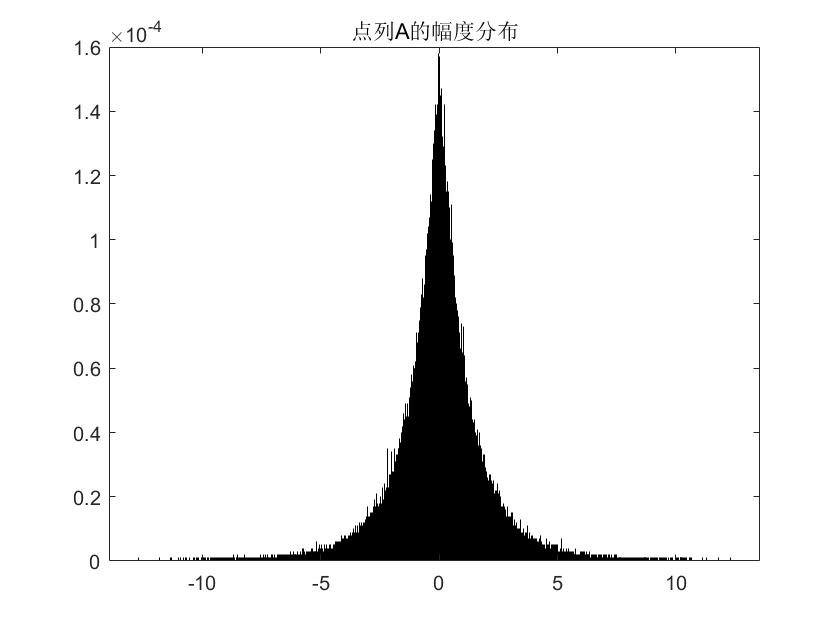

bins = 100000;               %选取合理的直方图格点数
histogram(A, bins,'Normalization','probability');
title("点列A的幅度分布");

## 8bit均匀量化

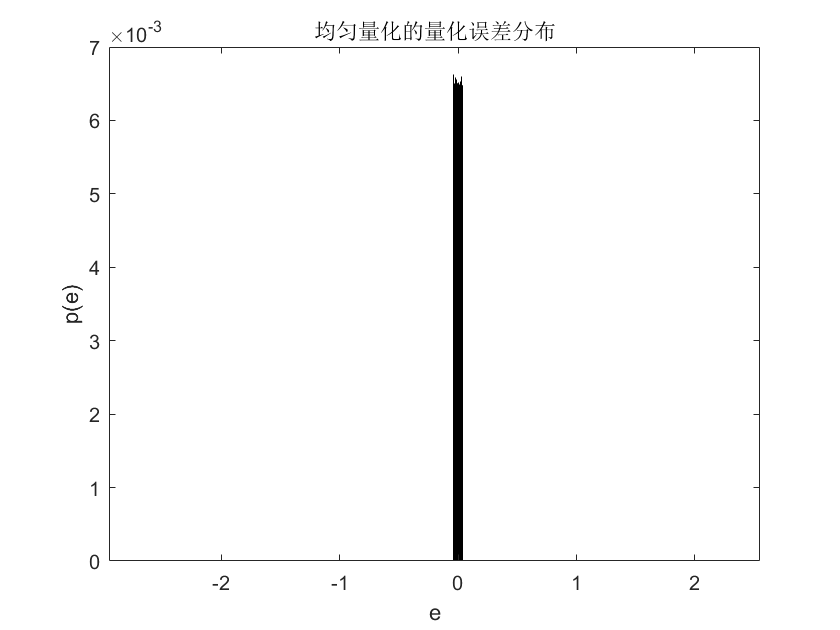

A_hat = zeros(size(A));                         %用于储存量化后的采样  
L = 2^8;                                        %量化区间
interval = 2*V_max/L;                           %量化间隔
x = [-V_max:interval:V_max];                    %分层电平
y = [(x(1)+x(2))/2:interval:(x(L)+x(L+1))/2];   %重建电平
for i = 1:N                                     %循环点列
    if(A(i)<-V_max)
        A_hat(i)=-V_max;
        continue;
    elseif(A(i)>V_max)
        A_hat(i)=V_max;
        continue;
    end
    for j = 1:L                                 %循环区间
        % 完成均匀量化，得到量化后的采样A_hat
        if(A(i)>=x(j) && A(i)<x(j+1))
            A_hat(i)=y(j);
            continue;
        end
    end
end
ex=A-A_hat;                                     %均匀量化的量化误差e(x)
power_exp = sum(A.^2)/N;                        %信号功率
noise_exp = sum(ex.^2)/N;                       %噪声方差
snr_exp = power_exp/noise_exp;
snrdb_exp = 10*log10(snr_exp);

figure;
nbins = 10000;                                  % 选取合理的直方图格点数
histogram(ex,nbins,'Normalization','probability');
title("均匀量化的量化误差分布")
xlabel("e")
ylabel("p(e)")

fprintf("均匀量化下，量化噪声方差%f,点列A信号功率%f,量化信噪比%fdB\n",noise_exp,power_exp,snrdb_exp);

均匀量化下，量化噪声方差0.000544,点列A信号功率1.995266,量化信噪比35.643171dB


## 对A进行µ律压缩得到点列B 

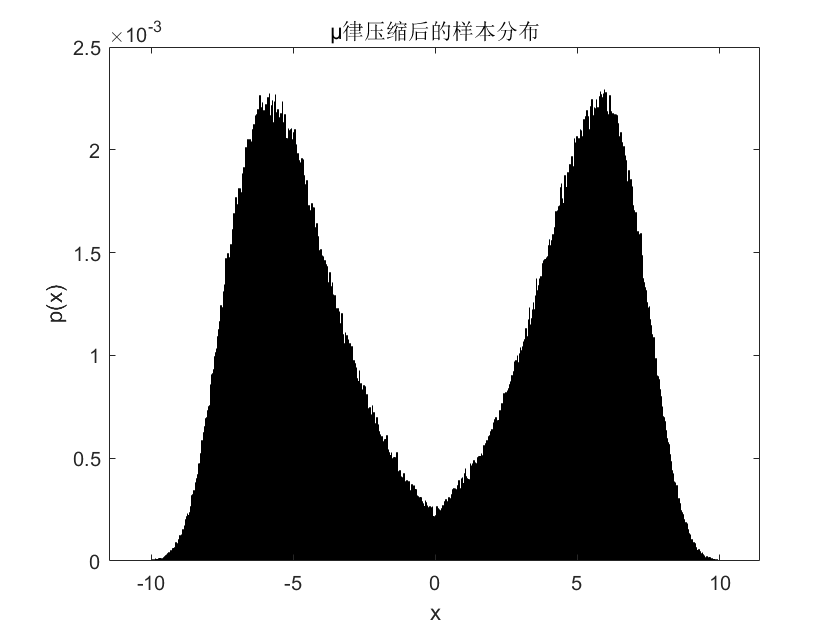

x_max = 10;                                     %上限取10
B = x_max*((log(1+mu*(abs(A)/x_max)))/(log(1+mu))).*(double(A>=0)*1+double(A<0)*(-1));
figure;
nbins_B=1000;                                    % 选取合理的直方图格点数
histogram(B,nbins_B,'Normalization','probability');
title("μ律压缩后的样本分布")
xlabel("x")
ylabel("p(x)")

## 对点列B进行8bit均匀量化得到点列C

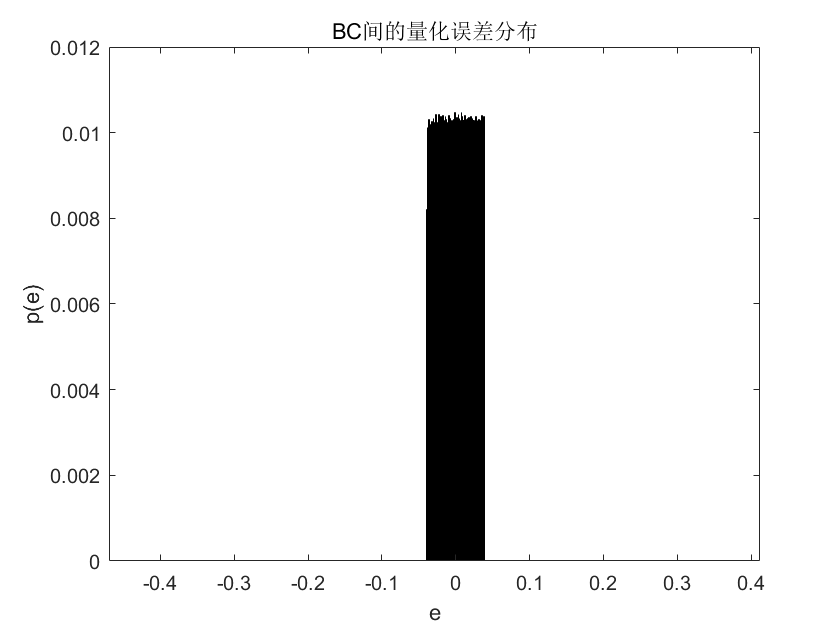

C = zeros(size(B));
L = 2^8;                                        %量化区间
interval = 2*V_max/L;                           %量化间隔
x = [-V_max:interval:V_max];                    %分层电平
y = [(x(1)+x(2))/2:interval:(x(L)+x(L+1))/2];   %重建电平
for i = 1:N                                     %循环点列
    if(B(i)<-V_max)
        C(i)=-V_max;
        continue;
    elseif(B(i)>V_max)
        C(i)=V_max;
        continue;
    end
    for j = 1:L                                 %循环区间
        % 完成均匀量化，得到量化后的采样A_hat
        if(B(i)>=x(j) && B(i)<x(j+1))
            C(i)=y(j);
            continue;
        end
    end
end
ex1=B-C;                                        %BC间的量化误差e(x)
powerBC_exp = sum(B.^2)/N;                      %信号功率
noiseBC_exp = sum(ex1.^2)/N;                    %噪声方差
snrBC_exp = powerBC_exp/noiseBC_exp;            %信噪比
snrBCdb_exp = 10*log10(snrBC_exp);              %信噪比dB
figure;
nbins_ex1=1000;                                 % 选取合理的直方图格点数
histogram(ex1,nbins_ex1,'Normalization','probability');
title("BC间的量化误差分布")
xlabel("e")
ylabel("p(e)")

fprintf("BC间,量化噪声方差%f,点列B信号功率%f,量化信噪比%fdB\n",noiseBC_exp,powerBC_exp,snrBCdb_exp);

BC间,量化噪声方差0.000509,点列B信号功率29.256202,量化信噪比47.597184dB


## 对点列C扩展得到点列D

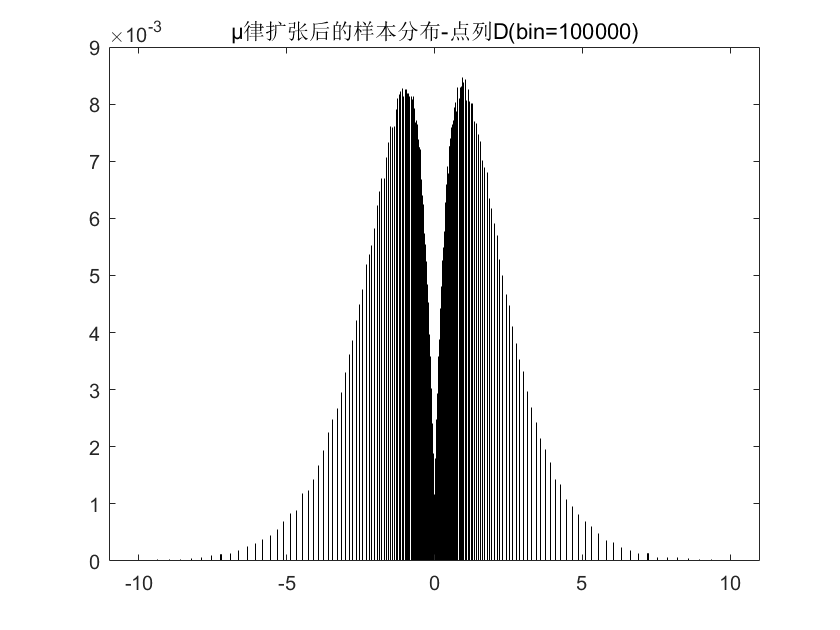

x_max = 10;
D=(x_max/mu)*( (1+mu).^(abs(C)/x_max) - 1 ).*(double(C>=0)*1+double(C<0)*(-1));

%我自己补一个，看看画出来D的效果
nbins_D=100000;
figure;
histogram(D,nbins_D,'Normalization','probability');
title("μ律扩张后的样本分布-点列D(bin="+num2str(nbins_D)+')');

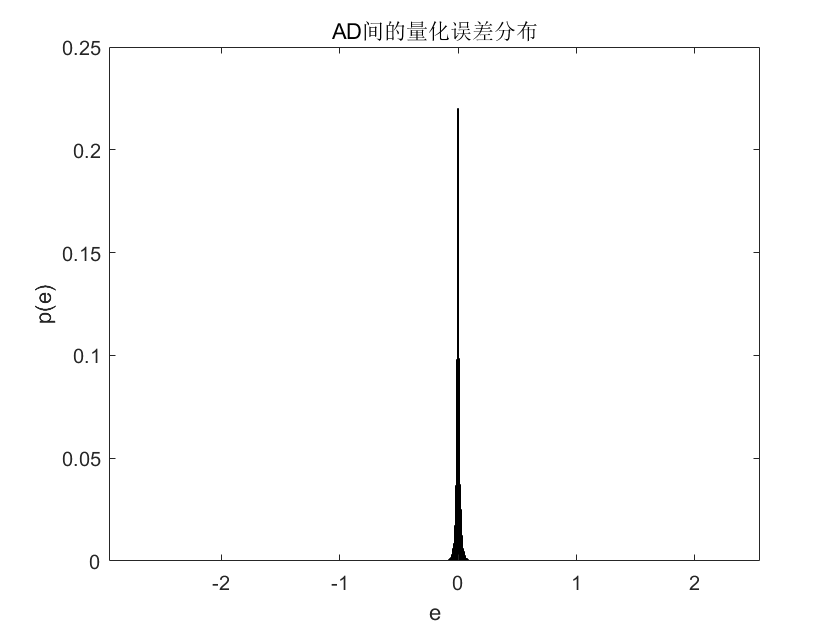


ex2=A-D;                                        %AD间的量化误差e(x)
powerAD_exp = sum(A.^2)/N;                      %信号功率
noiseAD_exp = sum(ex2.^2)/N;                    %噪声方差
snrAD_exp = powerAD_exp/noiseAD_exp;
snrADdb_exp = 10*log10(snrAD_exp);
figure;
nbins_ex2=1000;                                 % 选取合理的直方图格点数
histogram(ex2,nbins_ex2,'Normalization','probability');
title("AD间的量化误差分布")
xlabel("e")
ylabel("p(e)")

fprintf("AD间,量化噪声方差%f,点列A信号功率%f,量化信噪比%fdB\n",noiseAD_exp,powerAD_exp,snrADdb_exp);

AD间,量化噪声方差0.000358,点列A信号功率1.995266,量化信噪比37.461130dB
